**Log: **

[29-Nov-2020, SWC]: Used default options, average accuracy 88%. Poor accuracy with predicitng coalesced drops, which is often misclassified as doublets. However, accuracy for predicting doublets pretty good (93%). [edit 16-Dec-2020: might be due to imbalanced dataset?? there are more doublet images than other classes]

[30-Nov-2020, SWC]: Trained diffferent models using Classification Learner. highest accuracy achieved with Linear SVM (87%)

[15-Dec-2020; SWC]: Used all default options but trained only on 3 classes (singlet, doublet, coalesced). Then test trained model on new images generated.

**Questions**: 

1) Which feature detection and extraction?? --> SURF? SURF->bagoffeatures? SURF->bagoffeatures->PCA? feature learning??

2) Which classification model is most suitable -> preliminary run using classification learner using original training dataset & bag of features approach suggests SVM class classifer is best (though yet to try ensemble models)

3) What image size to use? Does it matter if aspect ratio not kept when resized?? 

**Workflow**: 

1) load training data 

2) run BagofFeatures on each image 

3) train on the different classification models 

**check if any statistical correlation between features and class label

**Background:**

- Bag of features appraoch is an approach for image category classification - also known as bag of words. 

- Model looks to categorise images into pre-defined set of labels

**Notes:**

- for this approach to be effective, majority of the object must be visible in the image.

**References:**

- bag of visual words concept - [https://uk.mathworks.com/help/vision/ug/image-classification-with-bag-of-visual-words.html](https://uk.mathworks.com/help/vision/ug/image-classification-with-bag-of-visual-words.html) 

- *bagOfFeature* documentation - [https://uk.mathworks.com/help/vision/ug/image-category-classification-using-bag-of-features.html](https://uk.mathworks.com/help/vision/ug/image-category-classification-using-bag-of-features.html) 

close all 
clear all 
clc 

## **1) Load Data**

path = fullfile('c:\','Users','chong','OneDrive - University of Birmingham','Year 4','RP - Machine Learning', 'TrainingDataSet');

% load images into data store; images stored in sub-folders according to category label 
% so can use as label source.
imds = imageDatastore(path, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
imds.ReadSize = numpartitions(imds); 
imds.ReadFcn = @(loc)imresize(imread(loc), [128,128]);

% count the number of images available in each category
tbl_count = countEachLabel(imds)

tbl_count = 3×2 table
       Label       Count
    ___________    _____

    Coalescence     110 
    Doublet         172 
    Singlet         108 


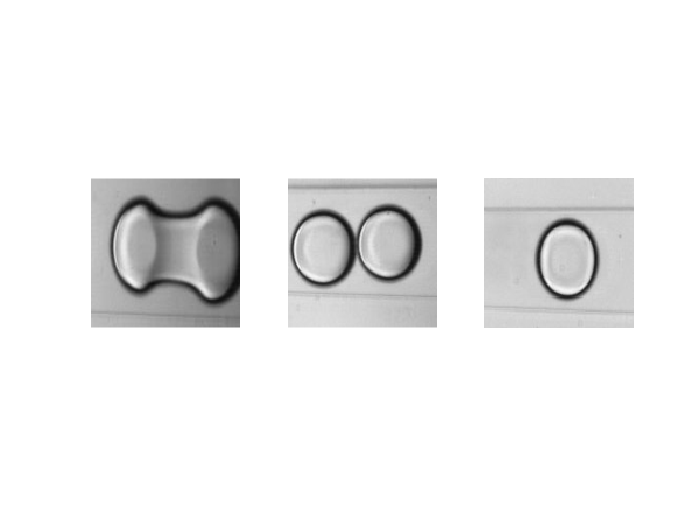

% load some images to check
sample = splitEachLabel(imds, 1, 'randomized'); 
for i = 1:length(tbl_count.Label)
    subplot(1,length(tbl_count.Label),i); 
    imshow(sample.readimage(i))
end

## 2) Data Preparation

% use split ratio: 70% training, 30% validation
[train_set, validation_set] = splitEachLabel(imds, 0.7, 'randomized');

% use split ratio: 80% training, 10% validation, 10% test
% [train_set, validation_set, test_set] = splitEachLabel(imds, 0.8, 0.1, 'randomized');

## 3) Create Visual Vocabulary - Feature Extraction

This is accomplished with a single call to *bagOfFeatures* function: 

- extracts SURF features from all images in all image categories 

- constructs the visual vocabulary by reducing the number of features through quantisation of feature space using K-menas clustering

*Note: bagOfFeatures* *object provides an encode method for counting the visual word occurances in an image. It produced a histogram that becomes a new and reduced representation of an image.*

bag = bagOfFeatures(train_set,'VocabularySize',500);

Creating Bag-Of-Features.
-------------------------
* Image category 1: Coalescence
* Image category 2: Doublet
* Image category 3: Singlet
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 273 images...done. Extracted 279552 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 3 has the least number of strongest features: 62259.
** Using the strongest 62259 features from each of the other image categories.

* Using K-Means clustering to create a 500 word visual vocabulary.
* Number of features          : 186777
* Number of clusters (K)      : 500

* Initializing cluster centers...100.00%.
* Clustering...completed 35/100 iterations (~1.53 seconds/iteration)...converged in 35 iterations.

* F

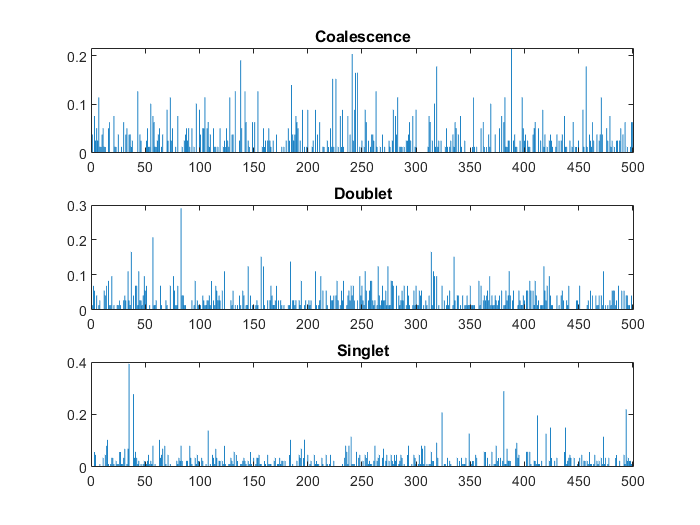

% load some images to check histogram
for i = 1:length(tbl_count.Label)
    subplot(length(tbl_count.Label),1,i); 
    featureVector = encode(bag, sample.readimage(i));
    bar(featureVector); title(char(tbl_count.Label(i)));
end

## 4) Train Classification Model: multiclass linear SVM classifier (using all default values)

classifier = trainImageCategoryClassifier(train_set, bag); 

Training an image category classifier for 3 categories.
--------------------------------------------------------
* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Encoding features for 273 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



## 5) Evaluate Classifier Performance

% santiy check: test with training set:
% this should produce a near perfect confusion matrix
confMatrix_check = evaluate(classifier, train_set);

Evaluating image category classifier for 3 categories.
-------------------------------------------------------

* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Evaluating 273 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                             PREDICTED
KNOWN          | Coalescence   Doublet   Singlet   
---------------------------------------------------
Coalescence    | 0.88          0.12      0.00      
Doublet        | 0.03          0.96      0.01      
Singlet        | 0.00          0.04      0.96      

* Average Accuracy is 0.93.



% then, test with validation set
confMatrix_valid = evaluate(classifier, validation_set);

Evaluating image category classifier for 3 categories.
-------------------------------------------------------

* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Evaluating 117 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                             PREDICTED
KNOWN          | Coalescence   Doublet   Singlet   
---------------------------------------------------
Coalescence    | 0.76          0.21      0.03      
Doublet        | 0.10          0.90      0.00      
Singlet        | 0.03          0.00      0.97      

* Average Accuracy is 0.88.



% compute average accuracy
fprintf('Average accuracy = %.2f%%', mean(diag(confMatrix_valid))*100)

Average accuracy = 87.67%

## 7) Apply trained classifier to classify new images

###     Load data

setdir = 'c:\Users\chong\OneDrive - University of Birmingham\Year 4\RP - Machine Learning';

sing = imageDatastore(fullfile(setdir,'TrainingData-generatedDec2020','Singlet'));
doub = imageDatastore(fullfile(setdir,'TrainingData-generatedDec2020','Doublet'));
coal = imageDatastore(fullfile(setdir,'TrainingData-generatedDec2020','Coalescence'));


sing.ReadFcn = @(loc)imresize(imread(loc), [128,128]);
doub.ReadFcn = @(loc)imresize(imread(loc), [128,128]);
coal.ReadFcn = @(loc)imresize(imread(loc), [128,128]);


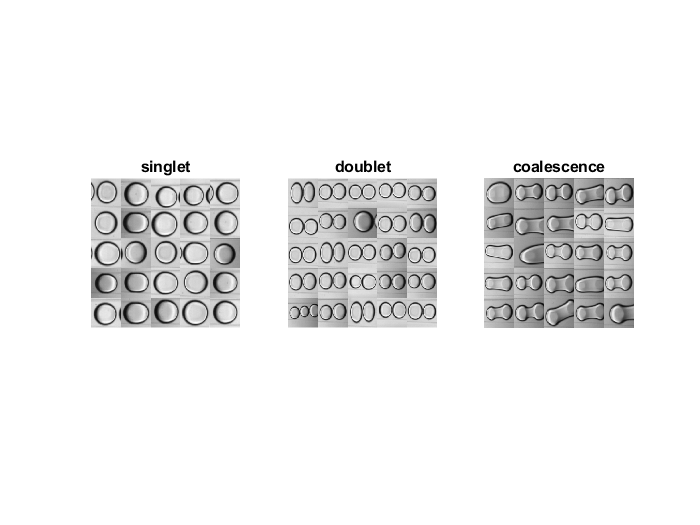

% load some images to check
figure; 
subplot(1,3,1); montage(sing,'Size',[5 5]); title('singlet')
subplot(1,3,2); montage(doub,'Size',[5 5]); title('doublet')
subplot(1,3,3); montage(coal,'Size',[5 5]); title('coalescence')

[Slab Sscore] = predict(classifier,sing);

Predicting categories using a multi-class classifier. Categories are:
---------------------------------------------------------------------

* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Processing 90 images...done.
* Finished processing all image sets.



[Dlab Dscore] = predict(classifier,doub);

Predicting categories using a multi-class classifier. Categories are:
---------------------------------------------------------------------

* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Processing 90 images...done.
* Finished processing all image sets.



[Clab Cscore] = predict(classifier,coal);

Predicting categories using a multi-class classifier. Categories are:
---------------------------------------------------------------------

* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Processing 52 images...done.
* Finished processing all image sets.



% plot confusion matrix 
predLabel = [Slab; Dlab; Clab];
trueLabel = [3*ones(90,1); 2*ones(90,1); ones(52,1)];

1 = coalescence;     2 = doublet;     3 = singlet

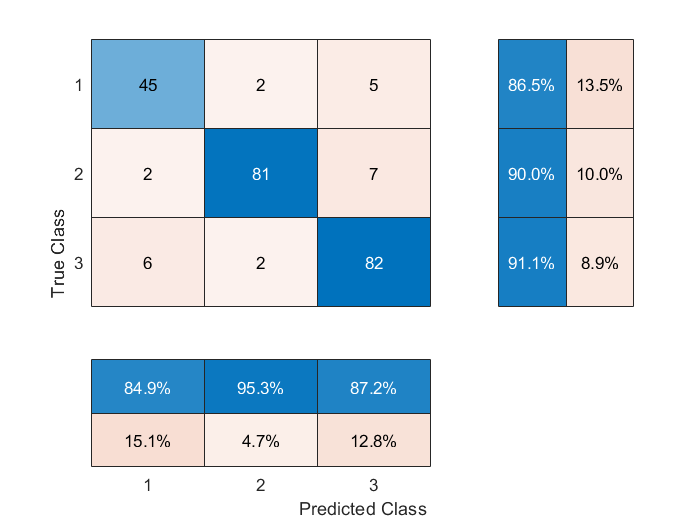

figure; confusionchart(trueLabel, predLabel, 'ColumnSummary', 'column-normalized', 'RowSummary','row-normalized')

## 1) Visualise misclassified images

###     Singlet

Sidx = []; Spred = [];
SDS = imageDatastore({});

for i = 1:length(Slab)
    if Slab(i) ~= 3;
        Spred = [Spred Slab(i)];
        Sidx = [Sidx i];
        SDS = imageDatastore(cat(1, SDS.Files, sing.Files(i)));
    end
end

table(Sidx',Spred','VariableNames',{'index','predicted class'})

ans = 8×2 table
    index    predicted class
    _____    _______________

     15             1       
     39             1       
     45             1       
     48             1       
     49             2       
     72             2       
     82             1       
     90             1       


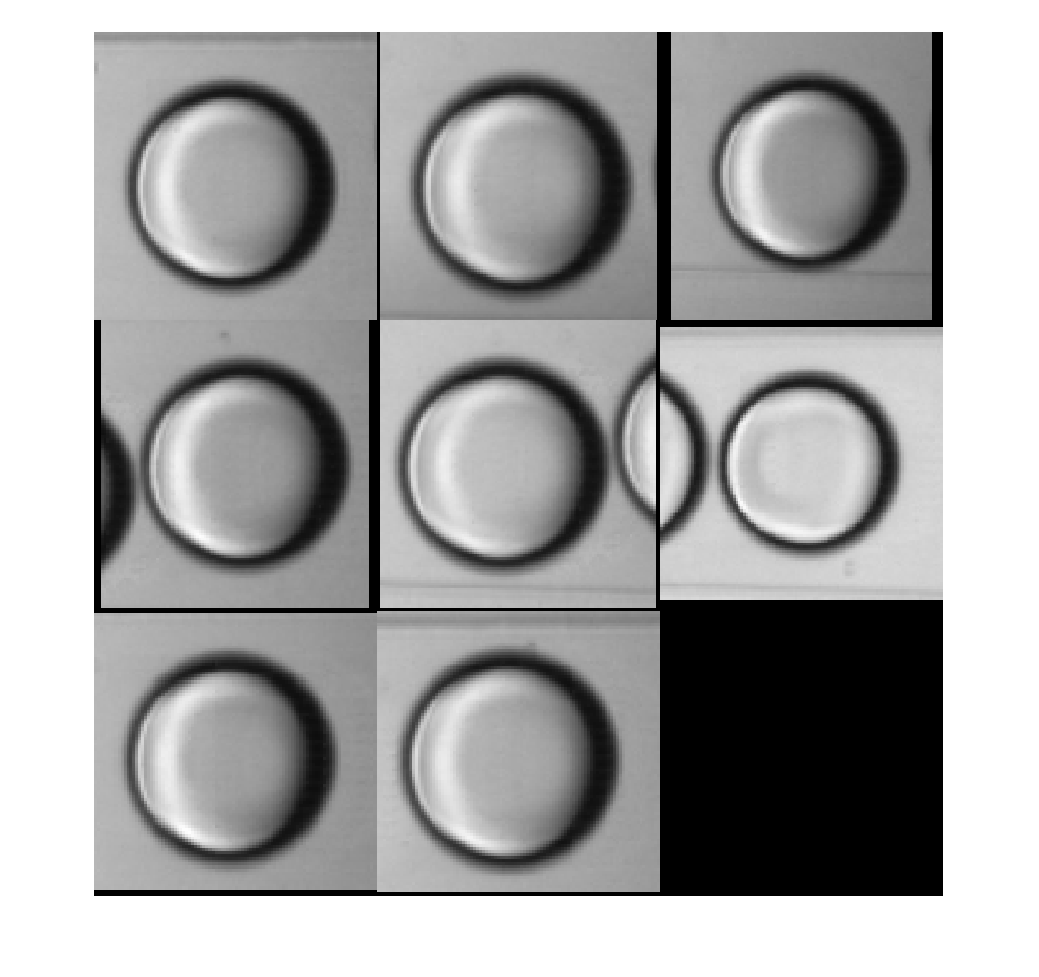


figure; montage(SDS); 

###     Doublet

Didx = []; Dpred = [];
DDS = imageDatastore({});

for i = 1:length(Dlab)
    if Dlab(i) ~= 2;
        Dpred = [Dpred Dlab(i)];
        Didx = [Didx i];
        DDS = imageDatastore(cat(1, DDS.Files, doub.Files(i)));
    end
end

table(Didx',Dpred','VariableNames',{'index','predicted class'})

ans = 9×2 table
    index    predicted class
    _____    _______________

      8             1       
     18             3       
     44             3       
     55             3       
     60             3       
     61             3       
     85             3       
     87             3       
     89             1       


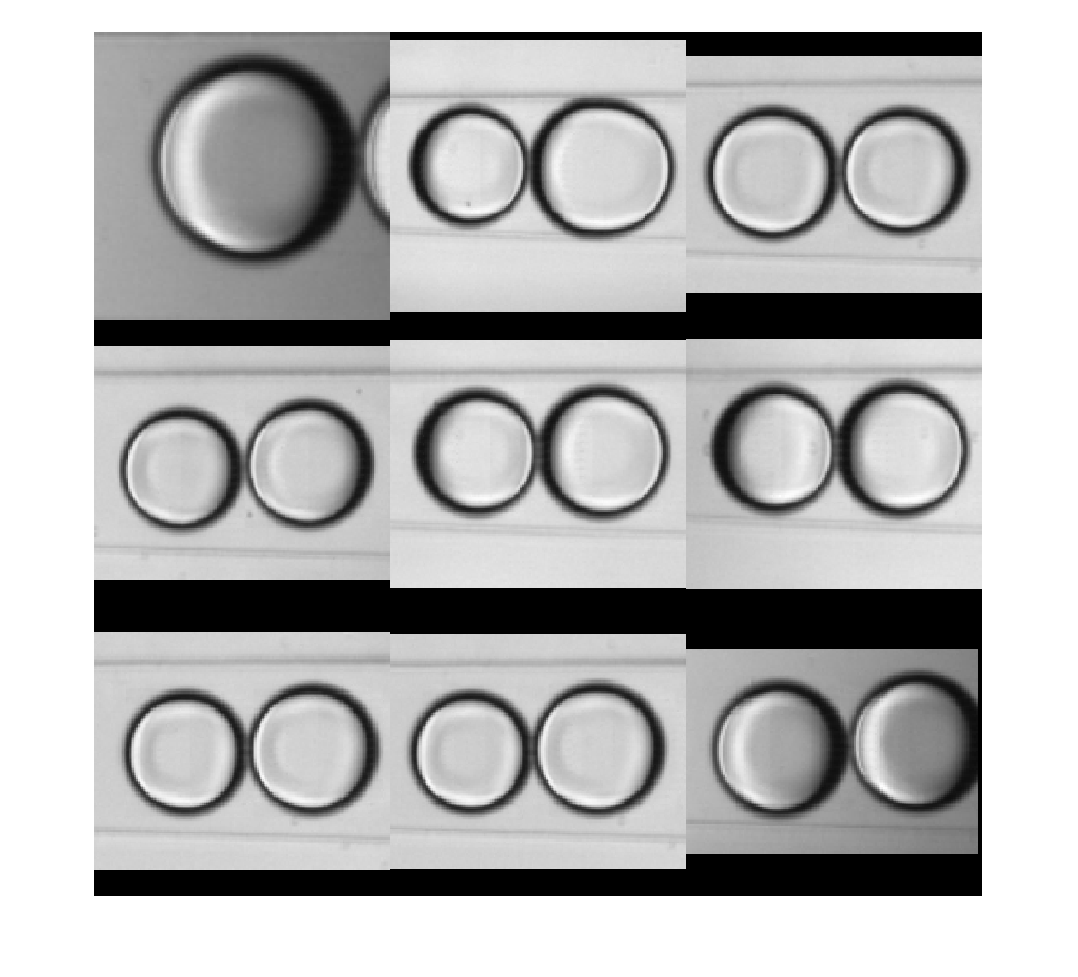


figure; montage(DDS);    

### Coalescence

Cidx = []; Cpred = [];
CDS = imageDatastore({});

for i = 1:length(Clab)
    if Clab(i) ~= 1;
        Cpred = [Cpred Clab(i)];
        Cidx = [Cidx i];
        CDS = imageDatastore(cat(1, CDS.Files, coal.Files(i)));
    end
end

table(Cidx',Cpred','VariableNames',{'index','predicted class'})

ans = 7×2 table
    index    predicted class
    _____    _______________

     10             3       
     11             3       
     16             3       
     19             3       
     27             2       
     37             3       
     39             2       


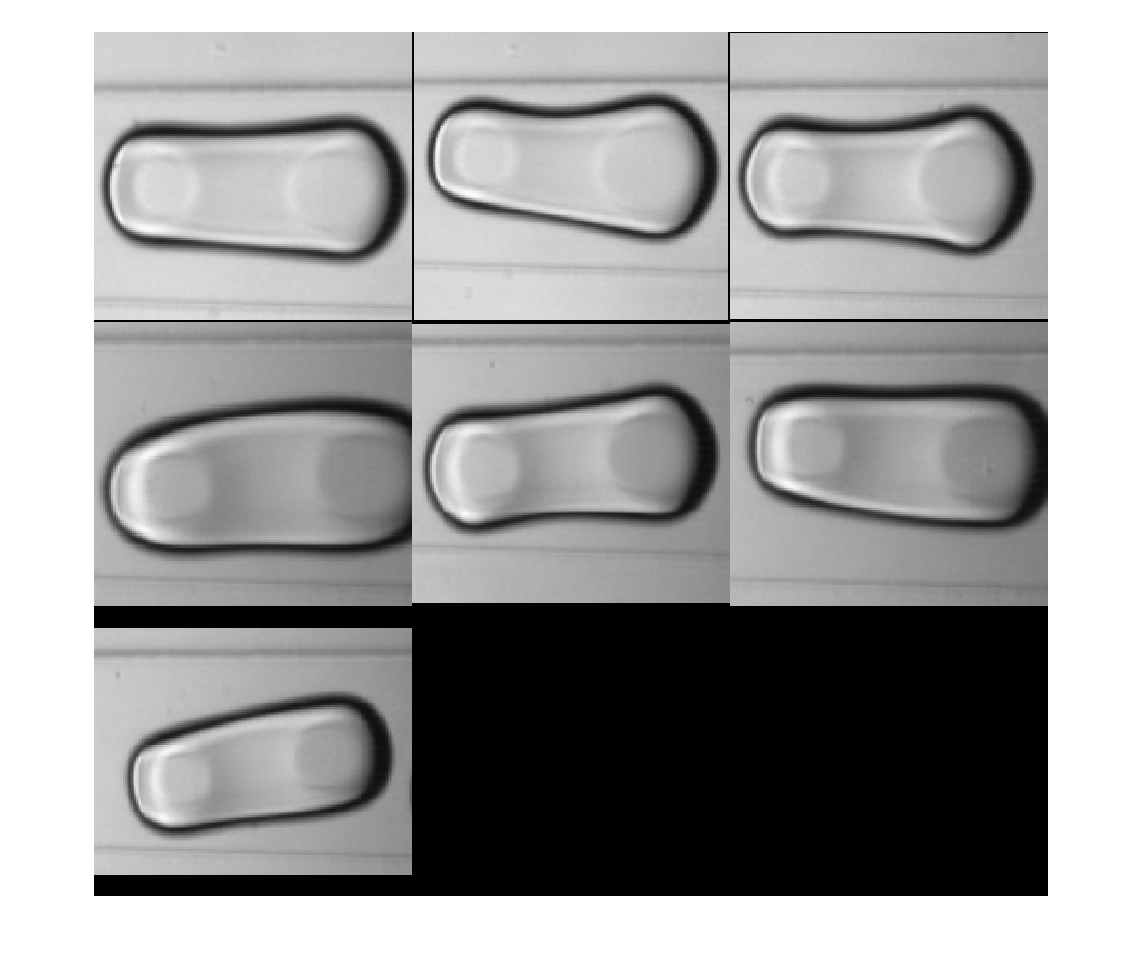


figure; montage(CDS); 

## 7) Try Different Classification Models - Classification Learner App

% % First need to create visual vocabulary for each image 
% train_data = double(encode(bag, train_set));
% % create table using the encoded features 
% train_data = array2table(train_data);
% % add label data to table 
% train_data.dropClass = train_set.Labels;

% % use the new features to train different models and assess their
% % performance
% classificationLearner